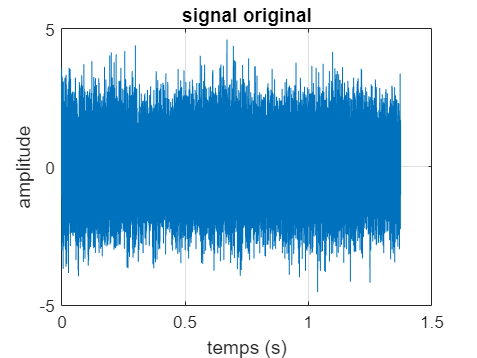

clear all;
close all;

% Question 1

% Initialisation
load('seqclavier.mat')
fe=32768;
Te=1/fe;
N=length(yb);
k=0:N-1;
t=k*Te;

% Tracé
figure
plot(t, yb)
title('signal original')
xlabel('temps (s)')
ylabel('amplitude')
grid on

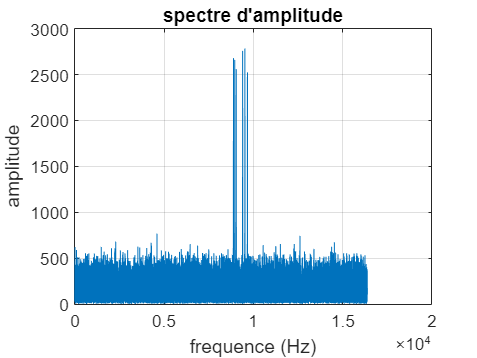


% Question 2

% Augmentation du nombre d'échantillons
Nf=2^nextpow2(4*N);
Yb=abs(fft(yb, Nf));
Yb=Yb(1:Nf/2);
k=0:Nf/2-1;
F=k/Nf*fe;

figure
plot(F, Yb)
title('spectre d''amplitude')
xlabel('frequence (Hz)')
ylabel('amplitude')
grid on

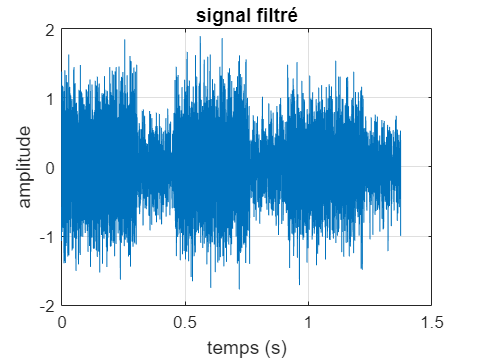



% De nombreuses fréquences sont supérieures à la fréquence max possible
% pour les touches appuyés, il faut donc filter le signal

% Question 3
fc=1500;
[A B]=butter(16, 2*fc/fe);
ybf=filtfilt(A, B, yb);

figure
plot(t, ybf)
title('signal filtré')
xlabel('temps (s)')
ylabel('amplitude')
grid on

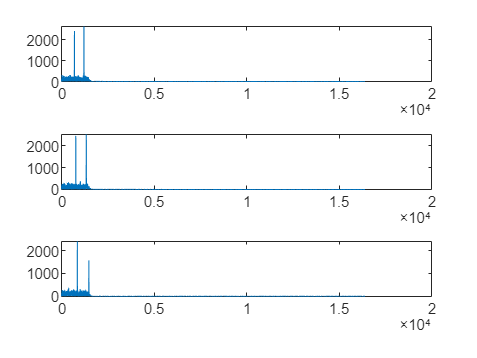


% Question 4

y1=ybf(1:15000);
Y1=abs(fft(y1, Nf));
Y1=Y1(1:Nf/2);

y2=ybf(15001:30000);
Y2=abs(fft(y2, Nf));
Y2=Y2(1:Nf/2);

y3=ybf(30001:45000);
Y3=abs(fft(y3, Nf));
Y3=Y3(1:Nf/2);

figure;
subplot(311);
plot(F, Y1)
% Touche 1

subplot(312);
plot(F, Y2)
% Touche 5 

subplot(313);
plot(F, Y3)

% Touche 9